## **Lecture 6 - Understanding and visualizing signals in neuroscience**

This script was prepared by Vered Kellner and Hugo Malagon Vina. Parts were inspired by the book Signal Processing for Neuroscientists by Wim van Drongelen. The data provided are property of Vered Kellner and Hugo Malagon Vina. 

### **Concept 1: Sampling and aliasing**

Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held


% Aliasing
% example signal
t=0:0.001:1; % 1 sec divided into ms steps
f=20; % Frequency in Hertz
signal=sin(2*pi*f*t);
% Simulate different sample rates and plot
figure
for skip=2:5:50
 plot(t,signal); hold; % The Original Signal
 plot(t(1:skip:1000),signal(1:skip:1000),'r');
 tt=['Sine', num2str(f), 'Hz: space bar to continue: SAMPLE RATE = ',... 
 num2str(1000/skip)]; 
 title(tt); 
 drawnow
 pause;
 clf;
end

#### Questions

L6-Q1.1 -  At what sampling frequency do you start seeing distortions in the signal?

L6-Q1.2 -  At what sampling frequency is the frequency of the sine wave no  longer 20Hz?

**Exercises**

L6-E.1 -Generate your own signal with a random frequency and test when the signal becomes distorted.

%Tip: use f = randi([imin,imax])

### **Concept 2: Plotting and peak detection**

%load the data
load Block6_signalData

% the most important thing you will learn is - ALWAYS LOOK AT YOUR DATA!
figure; plot(time, sigVals)


#### Questions

L6-Q2.1 - Describe the signal - what do you see that could be a source of information?

%Let's try to extract the peaks (in this case the action potentials)
%for this we need to first define a threshold - let's visualize different
%options
hold on; 
plot(time, repmat(median(sigVals),1,length(time)),'r')
plot(time, repmat(median(sigVals)+3*mad(sigVals),1,length(time)),'--r')

plot(time, repmat(mean(sigVals),1,length(time)),'m')
plot(time, repmat(mean(sigVals)+3*std(sigVals),1,length(time)),'--m')

#### Questions

L6-Q2.2: Which is better in this case - using the mean or the median?

% set a threshold (this should be visualized and defined for each dataset
% but should be comparable between conditions
threshold=median(sigVals)+3*mad(sigVals);
% Extract peaks above the defined threshold
[peaks, locs] = findpeaks(sigVals, 'MinPeakHeight', threshold);
plot(time(locs), peaks, 'go'); % Mark the detected peaks

**Exercises**

L6-E.2 - What happens when the signal is noisier? Try to find a good threshold and to detect the peaks when we add noise to the same signal. You can also look at the additional properties of 'findpeaks' to define more specific constraints on your peaks.

noisySig=sigVals + 15 * randn(size(sigVals));

### **Concept 3: Firing rates**

The data that will be used for this part is from recordings in the prelimbic cortex while mice are performing a task.

STMtx is a matrix -> where each column is a neuron and the rows are the spike times of that neuron (in sec).

We can calculate the firing rate of a neuron by counting the number of spikes during a given time.

% Calculating the firing rate of the first neuron of the STMtx matrix
clear; close all; %to close the figures and clear the workspace
load STMtx

Spike_Times = STMtx(~isnan(STMtx(:,1)),1);

Number_Spikes = length(Spike_Times);
Time = Spike_Times(end) - Spike_Times(1);
Firing_Rate = Number_Spikes/Time;


#### Questions

L6-Q3.1 - Please comment each line explaining what is happening.

**Exercises**

L6-E.3 - Create a script that calculates for each neuron in STMtx the firing rate and stores it in a vector (called FR) where each element is the Firing rate of one neuron. 

% The vector you create should be the same as the data given in FR.mat

% We can do an histogram to check the distribution of Firing rates
figure; hist(FR)

L6-E.4 Use the documentation of hist to play with the number of bins.

L6-Q3.2: What is your conclusion of the distribution of firing rates?

%Calculate the interspike interval and plot - for one neuron
interSpikeIntervals = diff(Spike_Times); % Calculate interspike intervals
figure; histogram(interSpikeIntervals, 30); % Plot histogram of interspike intervals
xlabel('Interspike Interval (s)');
ylabel('Count');
title('Distribution of Interspike Intervals');

L6-Q3.3: What information does the interspike interval histogram provide?

### **Concept 4: Autocorrelation / Autocorrelograms**

**What is an Autocorrelogram?**

An **autocorrelogram** is a tool used to study the **temporal structure** of a neuron’s spiking activity. It shows the **probability (or rate)** that a spike occurs at a certain **time lag** after (or before) another spike from the same neuron.

**How it’s Calculated**

- Take all the **spike times** of one neuron.

- Compute the **time differences** between every pair of spikes.

- Example: if spikes occur at 100 ms and 108 ms, the time difference is +8 ms.

- Count how often each time difference occurs within a defined time window (e.g., ±100 ms).

- Plot a **histogram** of those differences. this is the autocorrelogram.

The **x-axis** shows time lag (in milliseconds), and the **y-axis** shows how frequently spikes occur at that lag.

L6-E.5 - using the script plotAutocorrelogram.m, look for an example of regular, bursting or rhythmic neurons


% Using the pause "trick"
for i = 1:141 % if you want to check specific neurons, you can change the 1:141 for [4, 6, 7] for examples
    plotAutocorrelogram(STMtx, i, 0.001, 0.25)
    pause % You have to press any key to continue to the next neuron
end

### **Concept 5: Spiking relative to a stimulus**

**Task Description**

In this behavioral task, the animal makes a **choice between two sides** — **Left** or **Right** — on each trial.

- One side is designated as the **Gamble side**, and the other as the **Safe side**.

- The **Gamble side** offers a **reward with a variable probability**, which changes across different **blocks** of the session.

- The **Safe side** always provides a **reward with a fixed probability of 90%**.

- A block is a number of trials with the same probability of giving reward in Gamble. Normally, we have 3 consecutive blocks, each with a different probability. For example, B1 - 25%, B2 - 75% and B3 - 12.5%

The animal is **free to choose** which side to select on every trial.

Each trial follows a structured sequence:

- **Wheel Stop: **The animal begins the trial by stopping a wheel and waiting for **one second**.

- **Cue Presentation: **A cue appears, signaling that the animal can make a choice.

- **Choice Phase: **The animal selects either the **Gamble** or **Safe** side (Left or Right).

- **Outcome: **The chosen side determines whether a **reward** is delivered, based on the corresponding probability.

- **Inter-trial Interval: **After receiving (or not receiving) the reward, the animal waits **two seconds**.It then decides **when to initiate the next trial** by stopping the wheel again.

**Trial_Sync** -> A behavioural Matrix indicating information. Rows are trials and columns are:

1   'Trial Start (seconds from behavioural start)'

2   'Trial End (seconds from behavioural start)'

3   'Trial duration (seconds) (from the synchronisation)'

4   'Block number'

5   'Gamble Arm (Right = 1, Left = 0)'

6   'Probability Big Reward'

7   'Probability Small Reward'

8   'Ammount Big Reward'

9   'Ammount Small Reward'

10  'Number of previous wheel not stopping'

11  'Not responding trial'

12  'Chosen side (Right = 1, Left = 0)'

13  'Chosen arm (Gamble = 1, Safe = 0)'

14  'Rewarded trial'

15  'Start of the trial (Sampling points)' - the sampling rate is 20000 hz (To convert to seconds, divide sampling points by sampling rate)

16  'Cue presentation (Sampling points)'

17  'Start of response window (Sampling points)'

18  'Reward Period (Sampling points)'

19  'End of the trial (Sampling points)'

% If we want to know how many times the animal was rewarded, we can check
% the column number 14 "Rewarded Trial". In this column, a 1 means rewarded
% and a 0 means not rewarded. If I sum the ones in that column, it will
% tell me the number of times the animal got rewarded

Times_Rewarded = sum(Trials_Sync(:,14));
Percentage_Rewarded = Times_Rewarded/size(Trials_Sync,1);


L6-Q.4 - Explain what we did in the Percentage_Rewarded line

L6-E.6

We have a column "Chosen arm" which is 1 for gamble and 0 for safe.

Calculate the percentage of times that the animal got rewarded in gamble, and the percentage of times that it got rewarded in safe. TIP: You first need to find the indexes for gamble and safe, and then extract the rewarded information of those indexes

Then, do the same, but for each block. Explain what you see.

### Firing rate comparisons

We can compare the firing rates of diferent neurons on each block

% Finding the indexes for Block 1
Block1_Index = Trials_Sync(:,4) == 1;
Block2_Index = Trials_Sync(:,4) == 2;
Block3_Index = Trials_Sync(:,4) == 3;

% Extracting the behavioural data per blocks
Block1_Trials_Sync = Trials_Sync(Block1_Index,:);
Block2_Trials_Sync = Trials_Sync(Block2_Index,:);
Block3_Trials_Sync = Trials_Sync(Block3_Index,:);

SR = 20000; % We will need the Sampling Rate (SR)

% For block 1, find the firing rates of each neuron for each trial
for i = 1:size(Block1_Trials_Sync,1) % A for loop that will go for each trial in block 1
    for ii = 1:size(STMtx,2) % a for loop that will go for each neuron
        Spike_Times = STMtx(:,ii);
        Spikes_per_trial = sum(Spike_Times>(Block1_Trials_Sync(i,15)./SR) & Spike_Times<(Block1_Trials_Sync(i,19)./SR));
        Firing_Rate_Block1(i,ii) = Spikes_per_trial/((Block1_Trials_Sync(i,19)-Block1_Trials_Sync(i,15))./SR);
    end
end


L6-Q.5: Explain the code

L6-E.7

Create also the Firing rate matrices for the other blocks. You should end up with the same matrices as those in Firing_Blocks.mat

% We can use boxplot to check how different neurons change their firing
% rate. Also, to plot each point
boxplot(Firing_Rate_Block1(:,1))
hold on
for i = 1:length(Firing_Rate_Block1(:,1))
    x = randn(length(Firing_Rate_Block1(:,1)),1)*0.05 + i; % jitter around box position
    y = Firing_Rate_Block1(:,1);
    scatter(x, y, 40, 'filled', 'MarkerFaceAlpha', 0.6)
end

% We can also observed for a neuron in different blocks

Neuron_ID = 1;
data = [Firing_Rate_Block1(:,Neuron_ID); Firing_Rate_Block2(:,Neuron_ID); Firing_Rate_Block3(:,Neuron_ID)];
group = [ones(length(Firing_Rate_Block1(:,Neuron_ID)),1); 2*ones(length(Firing_Rate_Block2(:,Neuron_ID)),1); 3*ones(length(Firing_Rate_Block3(:,Neuron_ID)),1)];

figure;
boxplot(data, group); % no outlier symbols
hold on

% Overlay data points (with horizontal jitter)
g = unique(group);
for i = 1:length(g)
    x = randn(sum(group==g(i)),1)*0.05 + i; % jitter around box position
    y = data(group==g(i));
    scatter(x, y, 40, 'filled', 'MarkerFaceAlpha', 0.6)
end

L6-E.8

Find 3 neurons that increase their firing rate during the blocks and 3 neurons that decrease their firing rate during the blocks. Then, plot one figure where in the top three sub figures you have the boxplots of the 3 increasing and at the bottom the 3 decreasing. Label the plots with the neuron ID.

### Basic statistics

Using the groups, we can also do some basics statistics

%% Exploring Firing Rates Across Neurons

% Choose a few example neurons
example_neurons = [1 2 3];  % indices of neurons to explore

for n = example_neurons
    FRs = Firing_Rate_Block1(:, n);  % all trials for this neuron
    disp(['--- Neuron ', num2str(n), ' (Block 1) ---'])
    disp(['Mean firing rate: ', num2str(mean(FRs), '%.2f'), ' Hz'])
    disp(['Standard deviation: ', num2str(std(FRs), '%.2f')])
    disp(['Median firing rate: ', num2str(median(FRs), '%.2f')])
end

% Plot example neurons
figure;
plot(Firing_Rate_Block1(:, example_neurons));
xlabel('Trial');
ylabel('Firing rate (Hz)');
legend(compose('Neuron %d', example_neurons));
title('Firing Rates of Example Neurons (Block 1)');


#### Group comparisons

[n_trials, n_neurons] = size(Firing_Rate_Block1);

% Compare Neuron 1 vs Neuron 2 in Block 1
[~, p_ttest_neurons] = ttest2(Firing_Rate_Block1(:,1), Firing_Rate_Block1(:,2));

disp('--- t-test: Neuron 1 vs Neuron 2 (Block 1) ---')
disp(['p-value = ', num2str(p_ttest_neurons, '%.4f')])

% Compare Neuron 1 firing across Block 1 and Block 2
[~, p_ttest_blocks] = ttest2(Firing_Rate_Block1(:,1), Firing_Rate_Block2(:,1));

disp('--- t-test: Neuron 1 in Block 1 vs Block 2 ---')
disp(['p-value = ', num2str(p_ttest_blocks, '%.4f')])

#### One way ANOVA

neuron_idx = 1;
FRs_all = [Firing_Rate_Block1(:,neuron_idx); Firing_Rate_Block2(:,neuron_idx); Firing_Rate_Block3(:,neuron_idx)];
group_labels = [repmat({'Block 1'}, size(Firing_Rate_Block1,1), 1);
                repmat({'Block 2'}, size(Firing_Rate_Block2,1), 1);
                repmat({'Block 3'}, size(Firing_Rate_Block3,1), 1)];

[p_anova_neuron, ~, stats_neuron] = anova1(FRs_all, group_labels, 'off');
disp('--- One-way ANOVA: Neuron 1 across blocks ---')
disp(['p-value = ', num2str(p_anova_neuron, '%.4f')])


#### Exercises

L6-E.9

Add in the code above (for both ttest and ANOVA) the boxplot of the 2 distributions you are comparing, and in the title, the pvalue.

### Raster plot and PSTH

Be sure that the folder mlib6 is included in the path. In the File window (in matlab) right click and than add to path.

mlib6 is an older version of the MLIB software package for the analysis of neuronal spike data. This can be obtained at: [https://de.mathworks.com/matlabcentral/fileexchange/37339-mlib-toolbox-for-analyzing-spike-data](https://de.mathworks.com/matlabcentral/fileexchange/37339-mlib-toolbox-for-analyzing-spike-data)

the file exchange of matlab is a very good place to obtain packages and scripts; however, this has to be carefully selected as anybody could add scripts there.

Run the lines below. Try to understand, based on the code and the plots what are you seeing.

Play around with the values, and use the help function for the mpsth and the mraster to see what else could you do.

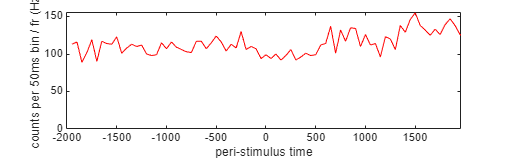

Neuron_ID = 50;
SR= 20000;
spxtimes = STMtx(~isnan(STMtx(:,Neuron_ID)),Neuron_ID);
trigtimes = Trials_Sync(:,18)./SR;

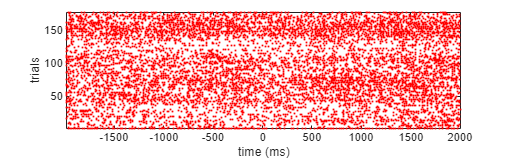

[psth, trialspx, ForError] = mpsth(spxtimes,trigtimes,'chart',1,'pre',2000,'post',2000,'binsz',50);

[rastmat timevec] = mraster(trialspx,2000,2000,'chart',1);


L6-E.8

Find 5 neurons that are responding to the action of selecting a side (meaning, between the cue presentation and before reward is given).

## Homework (optional, of course)

You can check the folder "Other Data Set". You will find there another session. Try to see what is inside! there are some very interesting neurons responding to reward! can you spot them?